# Read ThingSpeak Data

ThingSpeak stores data in a channel. To read data from a ThingSpeak channel, use the thingSpeakRead function and pass in the channel's ID number. Try reading data from channel 9.

thingSpeakRead(9)

ans =   374.0000   59.7028


To read more data from a ThingSpeak channel, use the "NumPoints" name-value pair and specify a number of points.

thingSpeakRead(9,"NumPoints",20)

ans =   380.0000   60.8068
  406.0000   61.2314
  408.0000   60.3822
  396.0000   61.0616
  403.0000   59.9575
  394.0000   58.3439
  386.0000   60.5520
  411.0000   58.3439
  393.0000   61.5711
  379.0000   59.7877


ThingSpeak stores the data with a datetime index. To see the index, specify an "OutputFormat" of timetable.

thingSpeakRead(9,"NumPoints",20,"OutputFormat","timetable")

ans = 20×2 timetable
         Timestamps         Light    OutsideTemperature
    ____________________    _____    __________________

    30-May-2019 18:09:36     406           61.231      
    30-May-2019 18:10:06     408           60.382      
    30-May-2019 18:10:36     396           61.062      
    30-May-2019 18:11:06     403           59.958      
    30-May-2019 18:11:36     394           58.344      
    30-May-2019 18:11:51     386           60.552      
    30-May-2019 18:12:21     411           58.344      
    30-May-2019 18:12:51     393           61.571      
    30-May-2019 18:13:06     379           59.788      
    30-May-2019 18:13:21     384           60.807      
    30-May-2019 18:13:36</

To calculate the average and maximum of "OutsideTemperature" for the past 24 hours, use thingSpeakRead with the "NumDays" and "OutputFormat" name-value pairs, assign the results to a variable, and use the mean and max MATLAB functions.

last24Hours = thingSpeakRead(9,"NumDays",1,"OutputFormat","timetable");
averageTemperature = mean(last24Hours.OutsideTemperature)

averageTemperature = 59.8017

maxTemperature = max(last24Hours.OutsideTemperature)

maxTemperature = 86.0297

To plot the last 24 hours of data, use the MATLAB plot function.

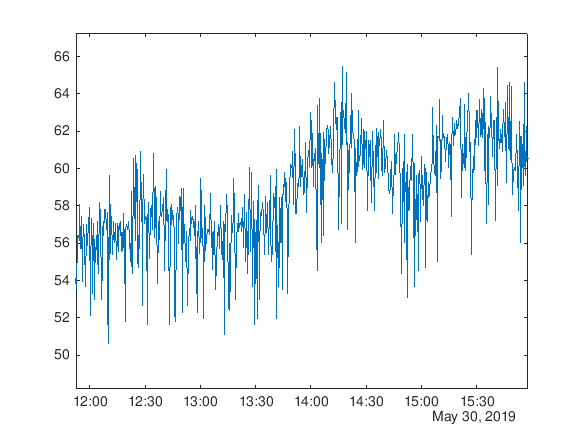

plot(last24Hours.Timestamps, last24Hours.OutsideTemperature)

# Set up ThingSpeak Account

- Visit [https://thingspeak.com](https://thingspeak.com)

- Click Sign In

- Enter your MathWorks Account email address and click Next

- Enter your MathWorks Account password and click Sign In 

# Example: Analyze Traffic Data

We used a Raspberry Pi, a webcam and ThingSpeak™ to count cars on a busy highway near MathWorks. We developed a car-counting algorithm using Simulink, and generated the image processing code for the Raspberry Pi. You can learn more by visiting the [project](https://www.mathworks.com/matlabcentral/fileexchange/52456-analyzing-traffic-using-a-webcam-a-raspberry-pi-and-thingspeak).

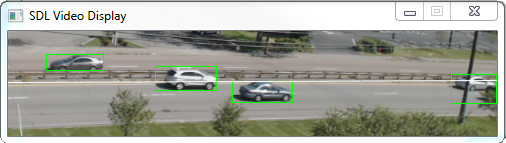

The density of cars for the east and west bound directions are stored in ThingSpeak [channel 38629](https://thingspeak.com/channels/38629).

Open [https://thingspeak.com/channels/38629](https://thingspeak.com/channels/38629) to see the public view of the traffic data.

 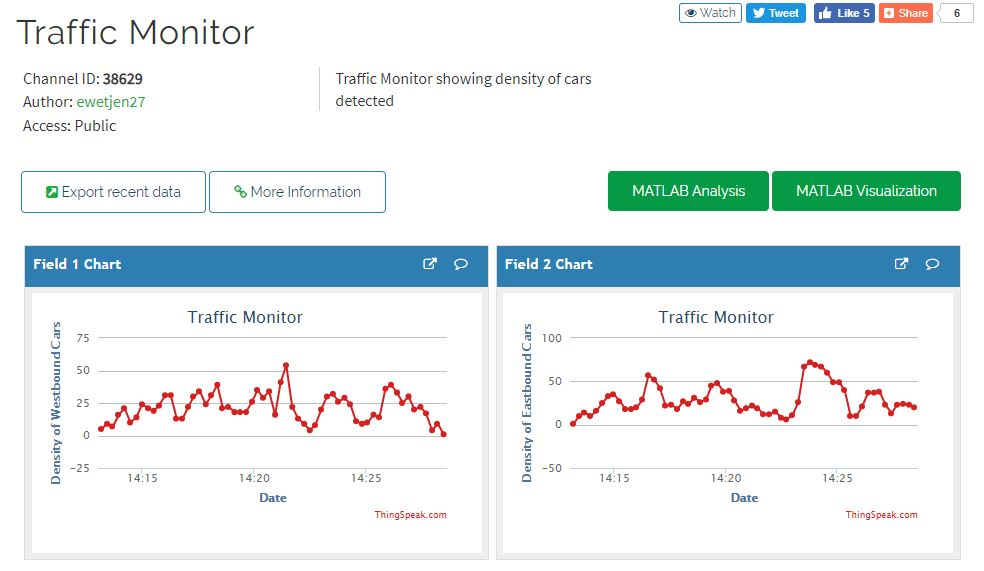

## Run MATLAB code on ThingSpeak

The same MATLAB code that you develop on desktop MATLAB or MATLAB Online can run on ThingSpeak.

To create a MATLAB Visualization to display on ThingSpeak, follow these steps:

1) From the top navigation bar on ThingSpeak, select ["Apps" and then "MATLAB Visualizations"](https://thingspeak.com/apps/matlab_visualizations)

2) Click "New", choose "Custom (no starter Code)", and click "Create" 

3) In the "Name" field, enter a name such as "My Traffic Analysis" 

4) In the "MATLAB Code" section, copy and paste the code below:

% Get data from the last 24 hours 
rte9Data = thingSpeakRead(38629,'NumDays',1,'OutputFormat','table'); 
 
% Calculate the median number of east bound cars in the past day 
disp('Median number of east bound cars in the past day') 

Median number of east bound cars in the past day


median(rte9Data.DensityOfEastboundCars) 

ans = 20

5) Scroll down and click the "Save and Run" button.  You'll see the latest readings from the car counter

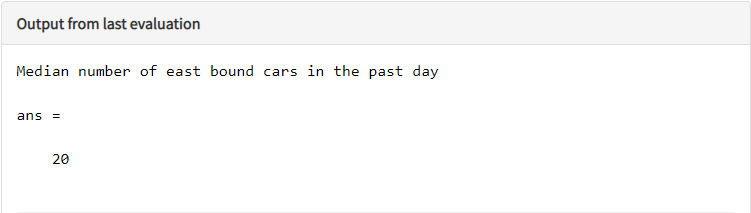

## Summarize one day of traffic data

The power of MATLAB is the flexibility to explore your data in many ways. 

1) Take the whole day of data, and display how many cars passed on an hourly basis. Erase your old code and copy and paste the following: 

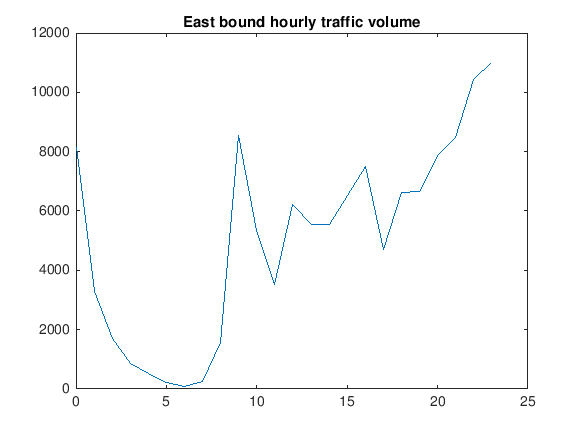

% Get data from the last 24 hours 
rte9Data = thingSpeakRead(38629,'NumDays',1,'OutputFormat','table'); 
 
% Group the data by hour of day, and sum readings within each hour 
hourOfDay = floor(hours(timeofday(rte9Data.Timestamps))); 
[G, hourOfDay] = findgroups(hourOfDay); 
eastBound = splitapply(@sum, rte9Data.DensityOfEastboundCars, G); 
 
% Plot the east bound volume by hour 
plot(hourOfDay, eastBound) 
% Feel free to customize the title 
title('East bound hourly traffic volume') 

2) Scroll down and click the "Save and Run" button. You'll see a plot of the number of cars that went eastbound in the past day. 

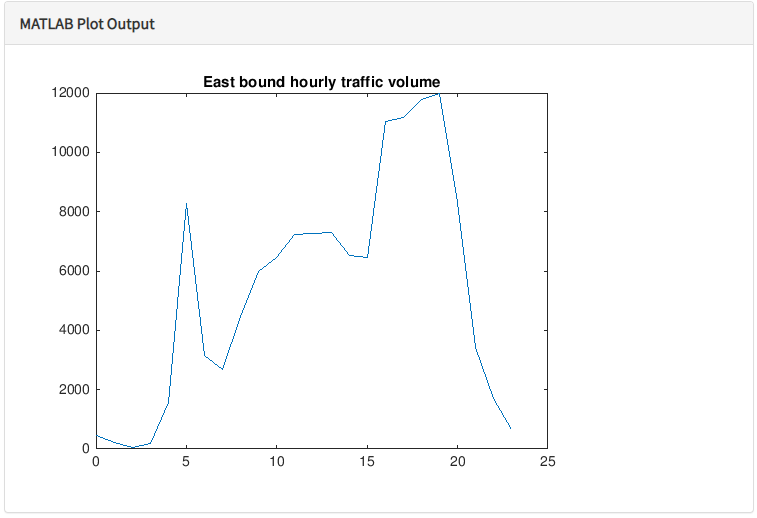

# Example: Merge Data From Two ThingSpeak Channels

I have two sensors outside of my office here in Natick, MA. One sensor is a temperature sensor that is sending data to ThingSpeak channel [163540](https://thingspeak.com/channels/163540). My other sensor is writing humidity data to channel [163545](https://thingspeak.com/channels/163545). Both channels are public. 

My goal is to plot temperature versus humidity over one time series. To accomplish this, I will use [timetable](https://www.mathworks.com/help/matlab/ref/timetable.html) and [synchronize](https://www.mathworks.com/help/matlab/ref/synchronize.html) inside of a new MATLAB Visualization on ThingSpeak.

## Read data from both channels

% Read from the temperature channel 
temperatureTT = thingSpeakRead(163540,'Fields',1,'NumPoints',100,'outputFormat','timetable');

% Read from the humidity channel 
humidityTT = thingSpeakRead(163545,'Fields',1,'NumPoints',100,'outputFormat','timetable');

## Synchronize both timetables

% Synchronize two timestables and fill in missing data using linear interpolation 
TT = synchronize(temperatureTT,humidityTT,'union','linear');

## Visualize the data

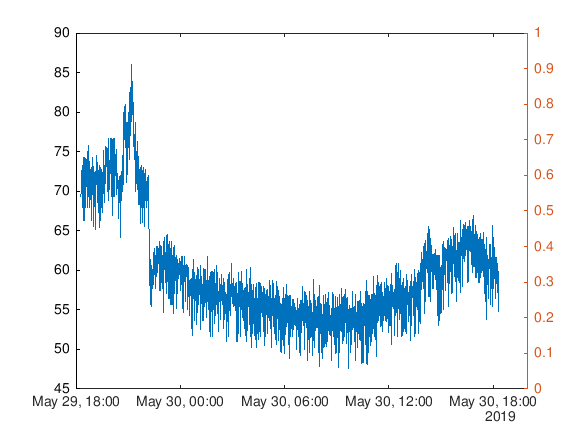

% Plot Temperature and Humidity over time
yyaxis left 
plot(TT.Timestamps,TT.Temperature) 

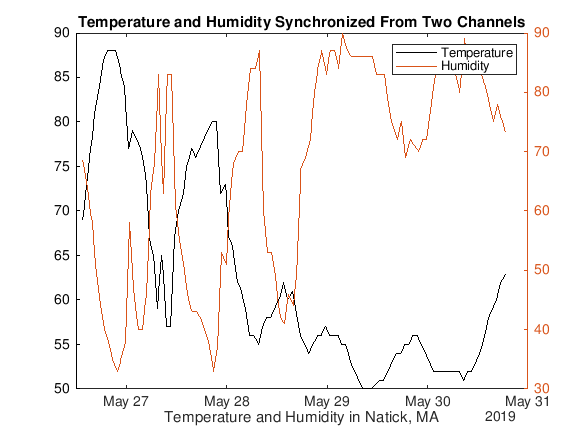

yyaxis right
plot(TT.Timestamps,TT.Humidity);  

title('Temperature and Humidity Synchronized From Two Channels') 
xlabel('Temperature and Humidity in Natick, MA') 
legend('Temperature','Humidity') 